# Computational Methods in Physics (PHY4605) - **Functions**

## Overview

Functions are programs that accept inputs and return outputs. They allow you to reuse sequences of commands and avoid storing temporary variables in the base workspace. You can create functions by using the `function` keyword and specifying the name, inputs, and outputs of the function. Functions can be stored in function files or script files, but they must follow certain rules for naming and placement. You can also add help text for your functions by inserting comments at the beginning of the function code.

## Function Definition

A function `funcName` defined in an m-file `funcName``.m` has the following general form:

- The function file must start with the keyword `function` (in the function definition line).

- The input and output arguments (`InArg1`, `InArg2`, etc.) are ‘dummy’ variables, and serve only to define the function’s means of communication with the workspace. Other variable names may therefore be used in their place when the function is called (referenced).

- Function names must follow the MATLAB rules for variable names. If the filename and the function definition line name are different, the internal name is ignored.

- When you type `help funcName`, MATLAB displays the comment lines that appear between the function definition line and the first noncomment (executable or blank) line.

A function m-file may contain the code for more than one function. The first function in a file is the primary function, and is the one invoked with the m-file name. Additional functions in the file are called subfunctions, and are visible only to the primary function and to other subfunctions. Each subfunction begins with its own function definition line. Subfunctions follow each other in any order after the primary function. 

Script file may also contains function definitions. Functions must be at the end of the file and the script file cannot have the same name as a function in the file.

### STEM Spotlight 💡: The Newton's Method

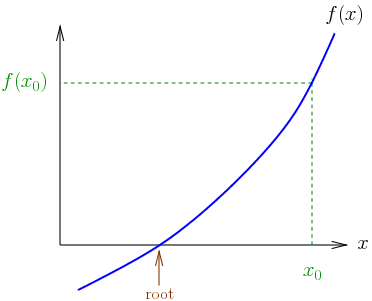

Newton’s method may be used to solve a general equation $f\left(x\right)=0$ by repeating the assignment $x$ becomes $x-\frac{f\left(x\right)}{f\prime \left(x\right)}$, where $f\left(x\right)$ (i.e., $\textrm{df}/\textrm{dx}$) is the first derivative of $f\left(x\right)$. The process continues until successive approximations to $x$ are close enough. Suppose that $f\left(x\right)=x^3 +x-3$, i.e., we want to solve the equation $x^3 +x-3=0$ (another way of stating the problem is to say we want to find the *zero* of $f\left(x\right)$). We have to be able to differentiate $f\left(x\right)$: $\textrm{df}/\textrm{dx}=3x^2 +1$. The `newtonSolver` function is defined in script file `newtonSolver.m`. The function accepts the initial estimate of $x$ and will stop either when the relative error in $x$ is less than ${10}^{-8}$, or after 20 steps. It can be called as follows:

InitialEstimate = 3
newtonSolver(InitialEstimate)
function newtonSolver(x)
% Solving a polynomial equation to determine the roots through the Newton's method
arguments
    x (1,1) double {mustBeNumeric} = 1
end
Step = 0; 
TargetError = 1e-8;
Error = 1;
disp('      x       f(x)');
while Error > TargetError && (Step < 20)
    xOld = x;
    x = x - f(x) / df(x);
    Step = Step + 1;
    disp([x f(x)]);
    Error = abs((x - xOld) / x);
end
if Error <= TargetError
    disp('Zero found at')
    disp(x)
else
    disp('Zero NOT found')
end
    % ↓ Other functions are nested in the primary function and act as supporting functions.
    % f(x) defines the original equation:
    function y = f(x)
        y = x^3 + x - 3;
    end
    % df(x) defines its first derivative:
    function y = df(x)
        y = 3*x^2 + 1;
    end
end

Use `which` to identify the directory where the function definition file is located:

which newtonSolver

### Argument Block

An `arguments` block declares input arguments for a function and is optional. If you include one or more arguments blocks, they must appear before the first executable line of the function. 

Each argument can have one or more restrictions or a default value, as shown in this syntax:

- `(dimensions)` — Input size, specified as a comma-separated list of two or more numbers. The dimensions of the input must match `(dimensions)` exactly or be *compatible* with the size specified by `(dimensions)`. For example, `(1,:)` specifies the input must be a 1-by-*n* row vector, but an *n*-by-1 column vector is also compatible. 

- `class` — Class or MATLAB data type specified by name, such as `double`. The input must be the specified type or a type that can be converted to that type.

- `{validators}` — Comma-separated list of validation functions, such as `mustBeNumeric` and `mustBeScalarOrEmpty`, enclosed in curly brackets. 

- `DefaultValue` — Default values must conform to the specified size, type, and validation rules. Specifying a default value makes the argument optional.

To demonstrate its usage, add the following block just below the help comments in the `newtonSolver``:`

Try running the following commands and see how does the function's behaviour change:

newtonSolver

newtonSolver(1:10)

newtonSolver('one')

Name-value arguments associate a name with a value that is passed to the function that:

- Can be passed to the function in any order

- Are always optional

To use name-value arguments, the `Optn``.InArgName `form is required, where `Optn` (arbitrarily named) is a structure name in the function signature and `InArgName `is the argument name in the arguments block.

The function `newtonSolver2` defined in `newtonSolver2` includes two optional name-value arguments. By having this type of arguments, the user can call the function as follows:

newtonSolver2(TargetError = 1e-9, InitialEstimate = 10)

which makes it easier to understand the meaning of each input argument passed to the function.

## Anonymous Function

An anonymous function is a function that is *not* stored in a program file, but is associated with a variable. Anonymous functions can accept multiple inputs and return one output. They can contain only a single executable statement.

The following are examples of anonymous function:

For example, create a handle to an anonymous function that finds the square of a number:

square = @(x) x.^2; 
x = 7;
x2 = square(x)

a = -3.9;
b = 52;
c = 0;
parabola = @(x) a*x.^2 + b*x + c;
y = parabola(10)

## Recursive Function

Many mathematical functions are defined recursively. In simpler words, a recursive function is a function that calls itself. The factorial function may be defined recursively as: $n!=n\times \left(n-1\right)!$ and may be written recursively like this:

If $n$ is larger than 1, let say, $n=3$, `fact(3)` will be invoked to compute `3 * fact(2)`. The same thing happens again for the function to compute `2 * fact(1)`, but this time, the function will just output 1. The function `fact` has been defined and can be called as follows:

fact(6)

### STEM Spotlight 💡: Legendre Polynomials

The first three Legendre polynomials are $P_0 \left(x\right)=1$, $P_1 \left(x\right)=x$, and $P_2 \left(x\right)=\left(3x^2 -1\right)/2$. There is a general recurrence formula for Legendre polynomials, by which they are defined recursively: $P_n \left(x\right)=\frac{\left(2n-1\right){\textrm{xP}}_{n-1} \left(x\right)-{\left(n-1\right)P}_{n-2} \left(x\right)}{n}$. The recursive function  `polyLegendre(n, x)` generates Legendre polynomials given the form of $P_0$ and $P_1$, where $n=2$ and $x=10$ with the following command:

polyLegendre(2, 10)

The result can be compared with the one obtained using the analytic form of $P_2 \left(x\right)$ given above. By using `polyLegendre`, polynomials for any values of $n$ and $x$ can be obtained, though.

**Local Functions**

function newtonSolver2(Optn)
arguments
    Optn.InitialEstimate (1,1) double = 1
    Optn.TargetError (1,1) {mustBeNumeric} = 1e-8
end
% Solving a polynomial equation to determine the roots through the Newton's method
Step = 0; 
Error = 1;
x = Optn.InitialEstimate;
disp('      x       f(x)');
while Error > Optn.TargetError && (Step < 20)
    xOld = x;
    x = x - f(x) / df(x);
    Step = Step + 1;
    disp([x f(x)]);
    Error = abs((x - xOld) / x);
end
if Error <= Optn.TargetError
    disp('Zero found at')
    disp(x)
else
    disp('Zero NOT found')
end
    % ↓ Other functions are nested in the primary function and act as supporting functions.
    % f(x) defines the original equation:
    function y = f(x)
        y = x^3 + x - 3;
    end
    % df(x) defines its first derivative:
    function y = df(x)
        y = 3*x^2 + 1;
    end
end

function f = fact(n)
% Obtain the factorial of n recursively
if n > 1
    f = n * fact(n - 1);
else
    f = 1;
end
end

function P = polyLegendre(n, x)
% Computes the nth order Legendre polynomial at the given values x using the recursive formula.
switch n
    case 0
        P = ones(size(x));
    case 1
        P = x;
    otherwise
        % Recursive call to compute P_{n-1}(x) and P_{n-2}(x)
        P1 = polyLegendre(n - 1, x);
        P2 = polyLegendre(n - 2, x);
        % Compute Pn(x) using the recursive formula
        P = ((2 * n - 1) * x .* P1 - (n - 1) * P2) / n;
end
end